General Info

load Primate_Result_Vertical.mat
sampling_rate = 19.9; 

2. Vertical Saccade

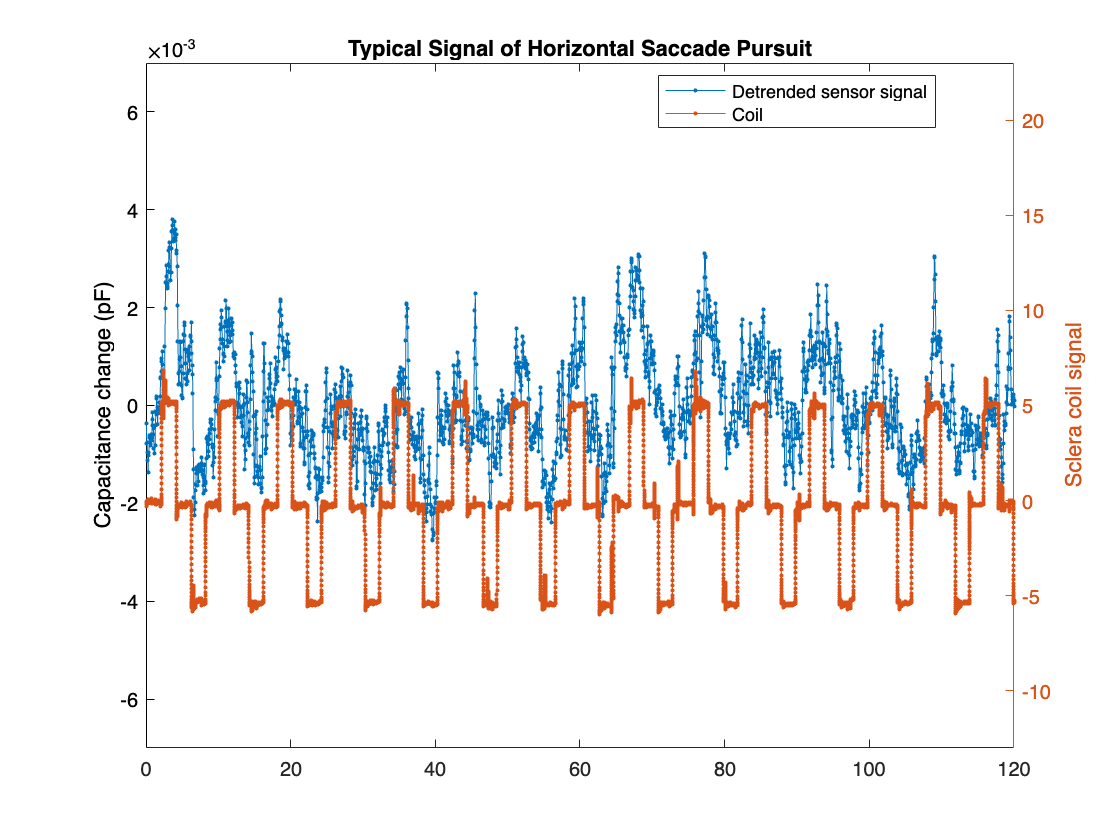

clf
capDataMain = -capDataSaccadeTracking;

csmall = find(capDataMain==min(capDataMain));
capDataMain(csmall) = [];

capDataMain = filloutliers(capDataMain,'previous','movmedian',10);

mainCoil = saccadeTracking;

coilTime = linspace(1,length(mainCoil),length(mainCoil))*0.001;
capTime = linspace(1,length(capDataMain),...
    length(capDataMain))/sampling_rate;

capDataPreproc = detrend(capDataMain,2);
capDataPreproc = circshift(capDataPreproc,15);


capDataProcessed = capDataPreproc;

yyaxis left
plot(capTime,movmean(capDataProcessed,5),'.-')
ylim([-7e-3 7e-3])
ylabel("Capacitance change (pF)")
hold on
yyaxis right
plot(coilTime,mainCoil,'.-')
ylabel("Sclera coil signal")
ylim([-13 23])
xlim([0 120])
hold off
legend("Detrended sensor signal","Coil",Location="best")
title("Typical Signal of Horizontal Saccade Pursuit")

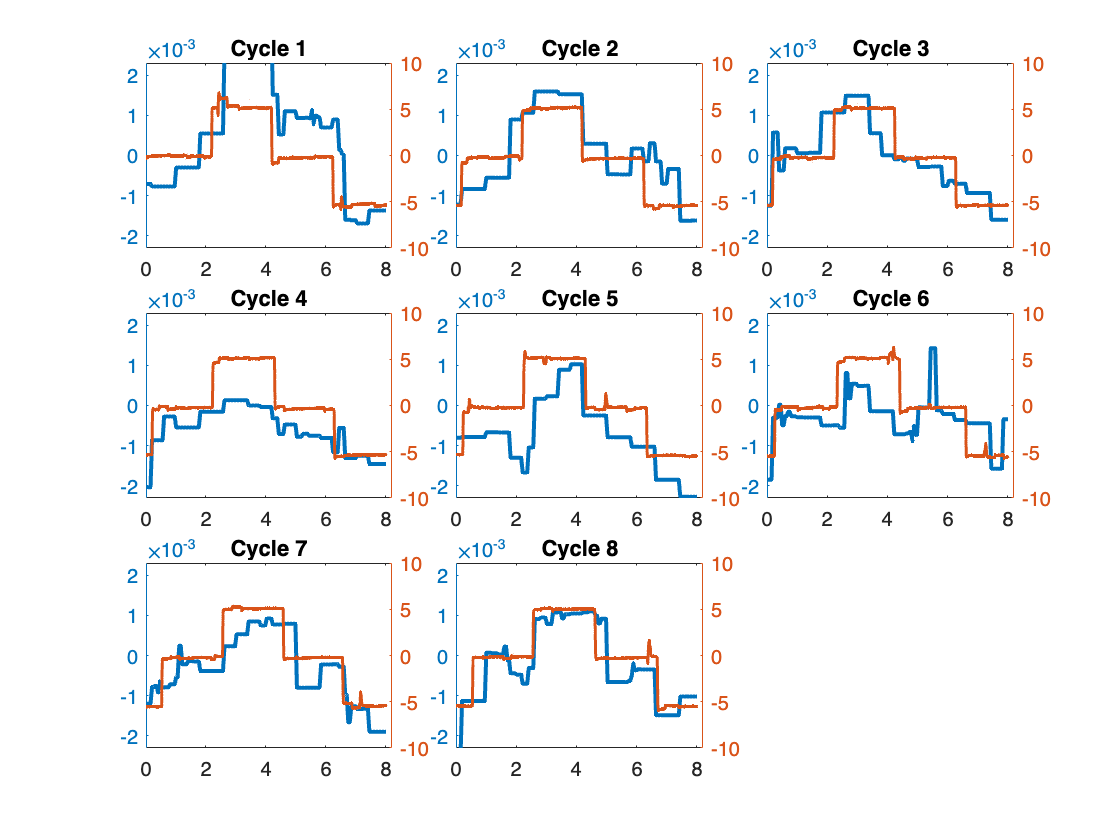

PERIOD_TIME  = 8;
WL_DEN_LVL = 4; 
WL_THR_MTD = 'Bayes'; 
WL_TYPE = 'bior1.5';
PEAK_PROM_CAP = .5e-3;
PEAK_PROM_COIL = 0.2;

START_TIME = 0;

capDataLocal = capDataPreproc;
coilDataLocal = mainCoil;

corra = zeros(1,9);
clear outarr


locs = floor(START_TIME*sampling_rate+1):floor(PERIOD_TIME*sampling_rate):length(capDataLocal);
coilLocs = 1000*START_TIME+1:floor(PERIOD_TIME*1000):length(coilDataLocal);
for peaknum = 1 : min([length(locs)-1 10]) % Maximum allowed = 10 segments

    outarr{peaknum,1} = wlcomp(capDataPreproc(locs(peaknum):locs(peaknum+1)),WL_TYPE,WL_DEN_LVL,0);

    outarr{peaknum,2} = capDataPreproc(locs(peaknum):locs(peaknum+1));

end
clear capvar coilvar
coilvar = [];
capvar = [];
clf
tiledlayout(3,3,'TileSpacing','tight')
for ix = 1:8 % 8 * 8 > 64
    nexttile
    if ix <= length(outarr)

        yyaxis left
        tsCap = linspace(0,PERIOD_TIME,length(outarr{ix,1}));
        tsCoil = linspace(0,PERIOD_TIME,PERIOD_TIME*1000 + 1.2);

        plot(tsCap, outarr{ix,1},LineWidth=2);
        hold on


        ylim([-2.3e-3 2.3e-3])


        yyaxis right

        plot(tsCoil,coilDataLocal(coilLocs(ix):coilLocs(ix+1)),LineWidth=1.5);
        hold on

        ylim([-10 10])
        hold off
        xlim([0 8.2])
        dsCoil = interp1(tsCoil,coilDataLocal(coilLocs(ix):coilLocs(ix+1)),tsCap);
        coilvar = [coilvar;dsCoil'];
        capvar = [capvar;outarr{ix,1}];
        mincorr = min(corrcoef(dsCoil,outarr{ix,1})); % RAW
        corra(1,ix) = mincorr(1);
    end
    title("Cycle " + ix);
end

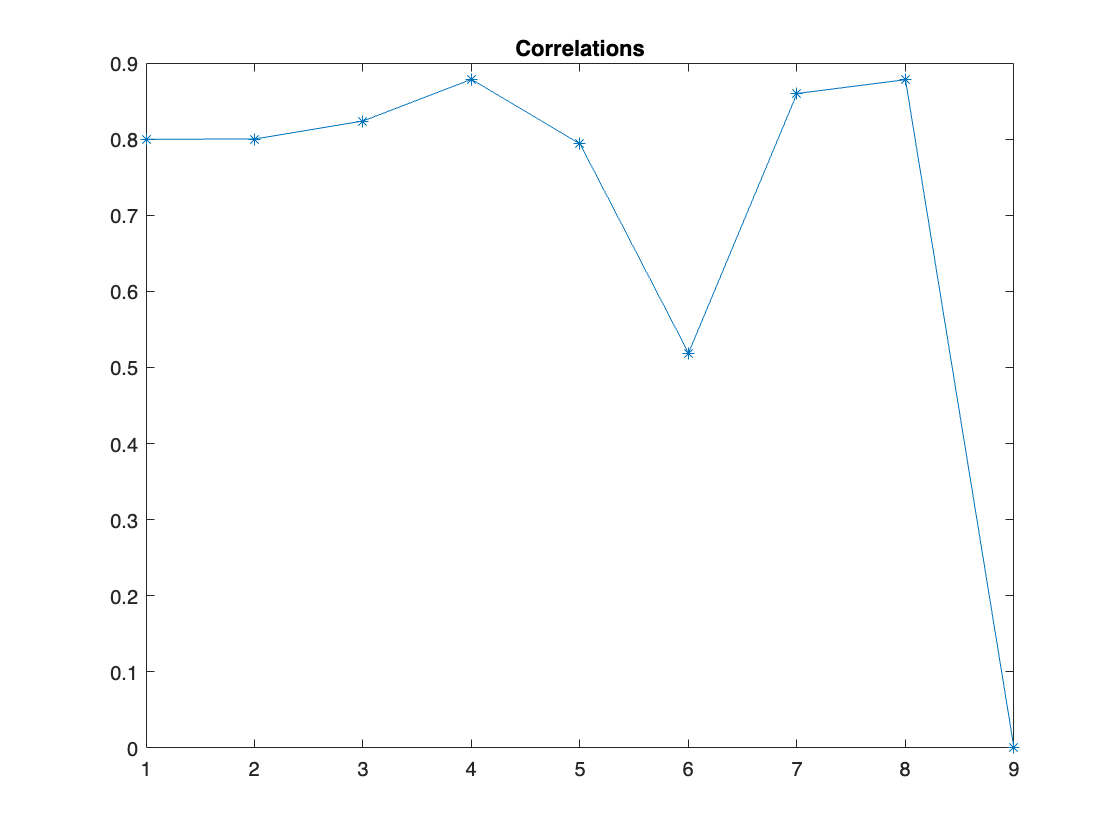

clf
plot(corra,"*-")
title("Correlations")

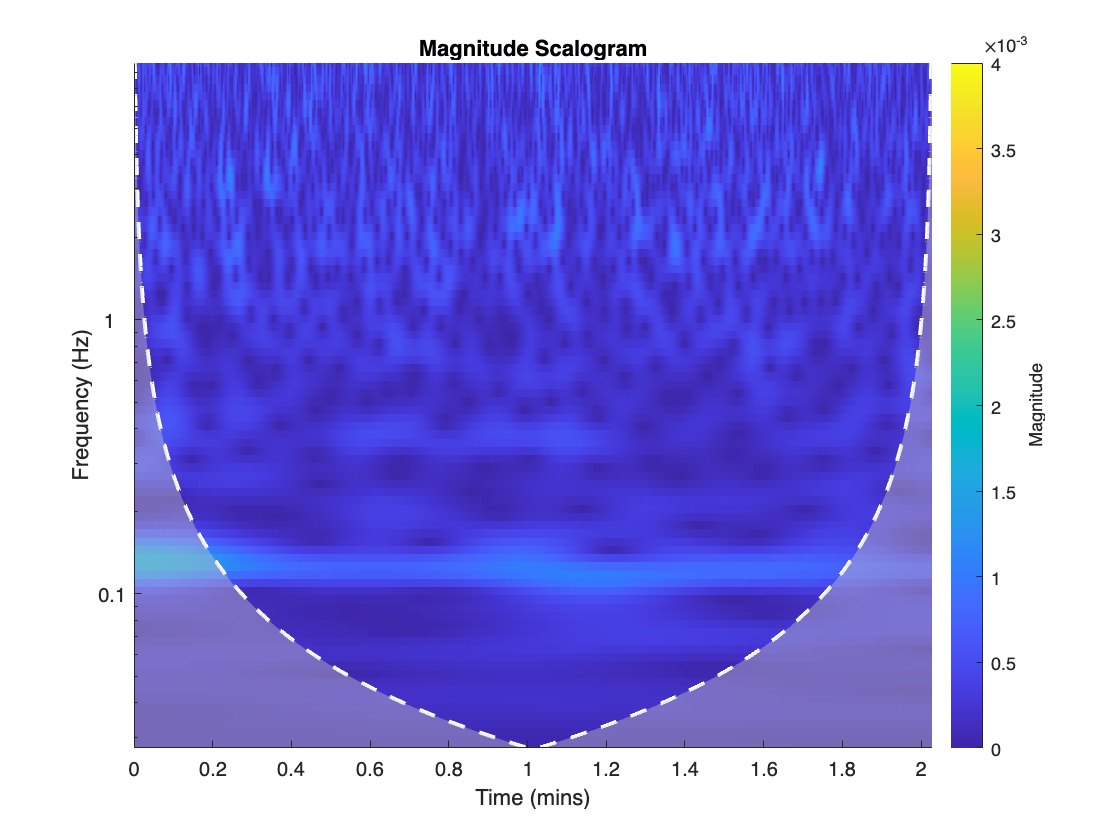

cwt(capDataPreproc,sampling_rate)
caxis([0 4e-3])

max(corra(corra ~= 0))

ans = 0.8785

mean(corra(corra ~= 0))

ans = 0.7941

std(corra(corra ~= 0))

ans = 0.1166

[xData, yData] = prepareCurveData( coilvar, capvar );
ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Robust = 'Bisquare';
[fitresult, gof] = fit( xData, yData, ft, opts );

4. Smooth

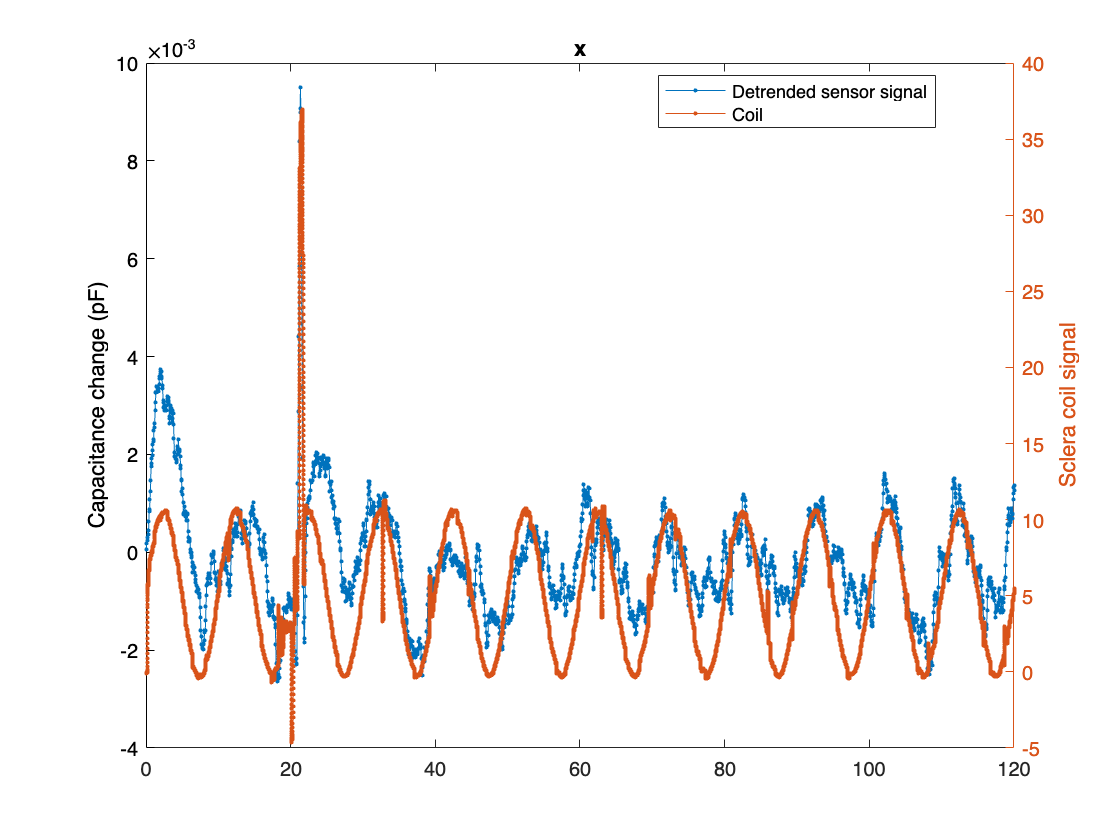

clf
capDataMain = -capDataSmoothPursuit;

csmall = find(capDataMain==min(capDataMain));
capDataMain(csmall) = [];

% Outlier removal optional
capDataMain = filloutliers(capDataMain,'previous','movmedian',10);

mainCoil = SmoothPursuit;

coilTime = linspace(1,length(mainCoil),length(mainCoil))*0.001;
capTime = linspace(1,length(capDataMain),...
    length(capDataMain))/sampling_rate;

%= Data Preprocessing
capDataPreproc = detrend(capDataMain,1);
capDataPreproc = circshift(capDataPreproc,-20);

%=
% Data Processing Handle fx
capDataProcessed = capDataPreproc;
%=

yyaxis left
plot(capTime,movmean(capDataProcessed,10),'.-')
% ylim([-7e-3 7e-3])
ylabel("Capacitance change (pF)")
hold on
yyaxis right
plot(coilTime,mainCoil,'.-')
ylabel("Sclera coil signal")
% ylim([-13 23])
xlim([0 120])
hold off
legend("Detrended sensor signal","Coil",Location="best")
title("x")

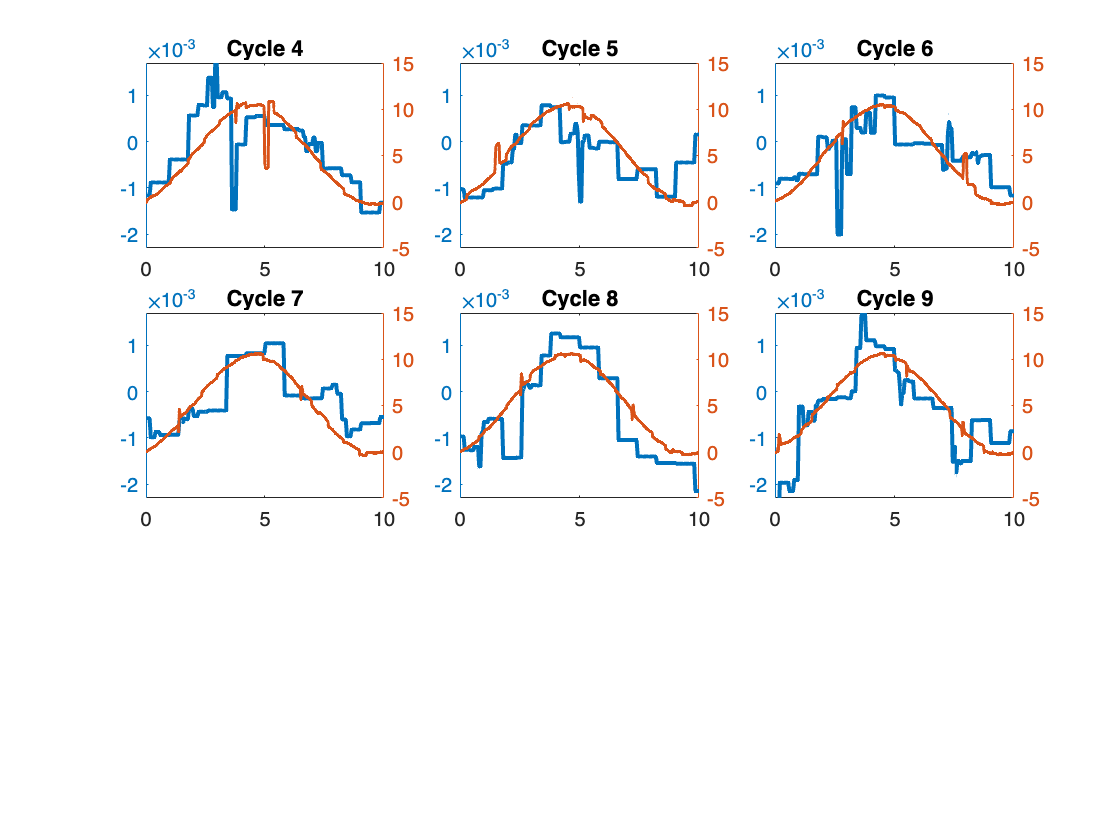

% [pks,locs] = findpeaks(-capDataProcessed,MinPeakDistance = sampling_rate*7.95);
PERIOD_TIME  = 10;
WL_DEN_LVL = 4; % n < log2_sampleAmount
WL_THR_MTD = 'Minimax'; % Bayes , BlockJS, FDR, Minimax, SURE 
WL_TYPE = 'bior1.5';
PEAK_PROM_CAP = .5e-3;
PEAK_PROM_COIL = 0.2;

START_TIME = 28;

capDataLocal = capDataPreproc;
coilDataLocal = mainCoil;

corra = zeros(1,9);
clear outarr


locs = floor(START_TIME*sampling_rate+1):floor(PERIOD_TIME*sampling_rate):length(capDataLocal);
coilLocs = 1000*START_TIME+1:floor(PERIOD_TIME*1000):length(coilDataLocal);
for peaknum = 1 : min([length(locs)-1 10]) 

    outarr{peaknum,1} = wlcomp(capDataPreproc(locs(peaknum):locs(peaknum+1)),WL_TYPE,WL_DEN_LVL,0);

    outarr{peaknum,2} = capDataPreproc(locs(peaknum):locs(peaknum+1));

end
clear capvar coilvar
coilvar = [];
capvar = [];
clf
tiledlayout(3,3,'TileSpacing','tight')
for ix = 4:9 % 6 * 10
    nexttile
    if ix <= length(outarr)

        yyaxis left
        tsCap = linspace(0,PERIOD_TIME,length(outarr{ix,1}));
        tsCoil = linspace(0,PERIOD_TIME,PERIOD_TIME*1000 + 1.2);

        plot(tsCap, outarr{ix,1},LineWidth=2);
        hold on


        ylim([-2.3e-3 1.7e-3])


        yyaxis right

        plot(tsCoil,coilDataLocal(coilLocs(ix):coilLocs(ix+1)),LineWidth=1.5);
        hold on

        ylim([-5 15])
        hold off
        xlim([0 10])
        dsCoil = interp1(tsCoil,coilDataLocal(coilLocs(ix):coilLocs(ix+1)),tsCap);
        coilvar = [coilvar;dsCoil'];
        capvar = [capvar;outarr{ix,1}];
        mincorr = min(corrcoef(dsCoil,outarr{ix,1})); % RAW
        corra(1,ix) = mincorr(1);
    end
    title("Cycle " + ix);
end

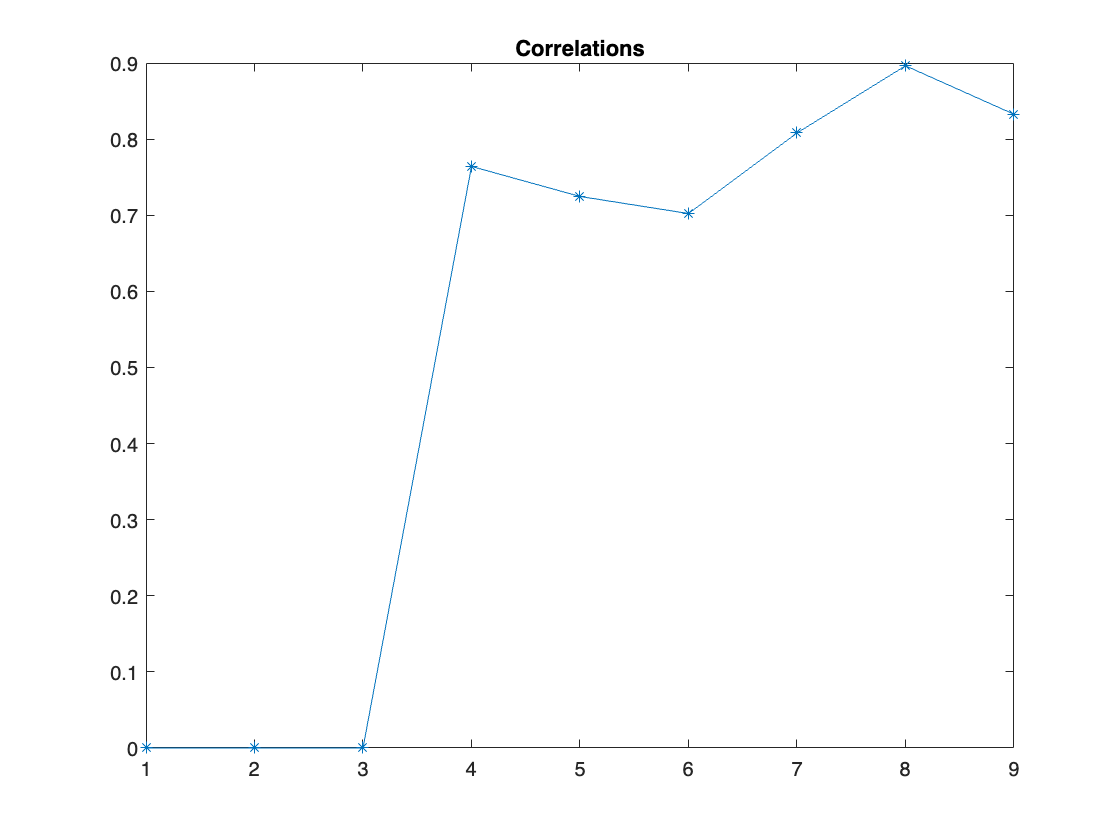

clf
plot(corra,"*-")
title("Correlations")

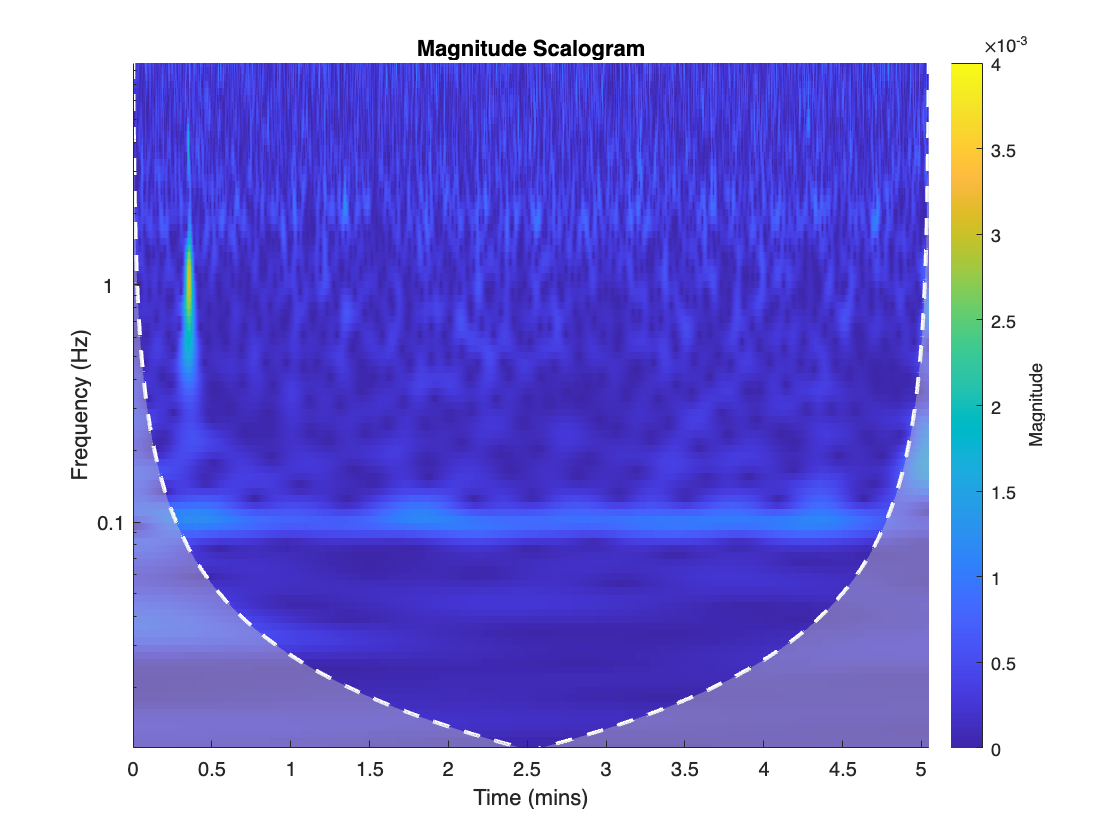

cwt(capDataPreproc,sampling_rate)
caxis([0 4e-3])

max(corra(corra ~= 0))

ans = 0.8963

mean(corra(corra ~= 0))

ans = 0.7880

std(corra(corra ~= 0))

ans = 0.0722

[xData, yData] = prepareCurveData( coilvar, capvar );
ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Robust = 'Bisquare';
[fitresult, gof] = fit( xData, yData, ft, opts );

5. Smooth with 5 degrees offset_0.2hz

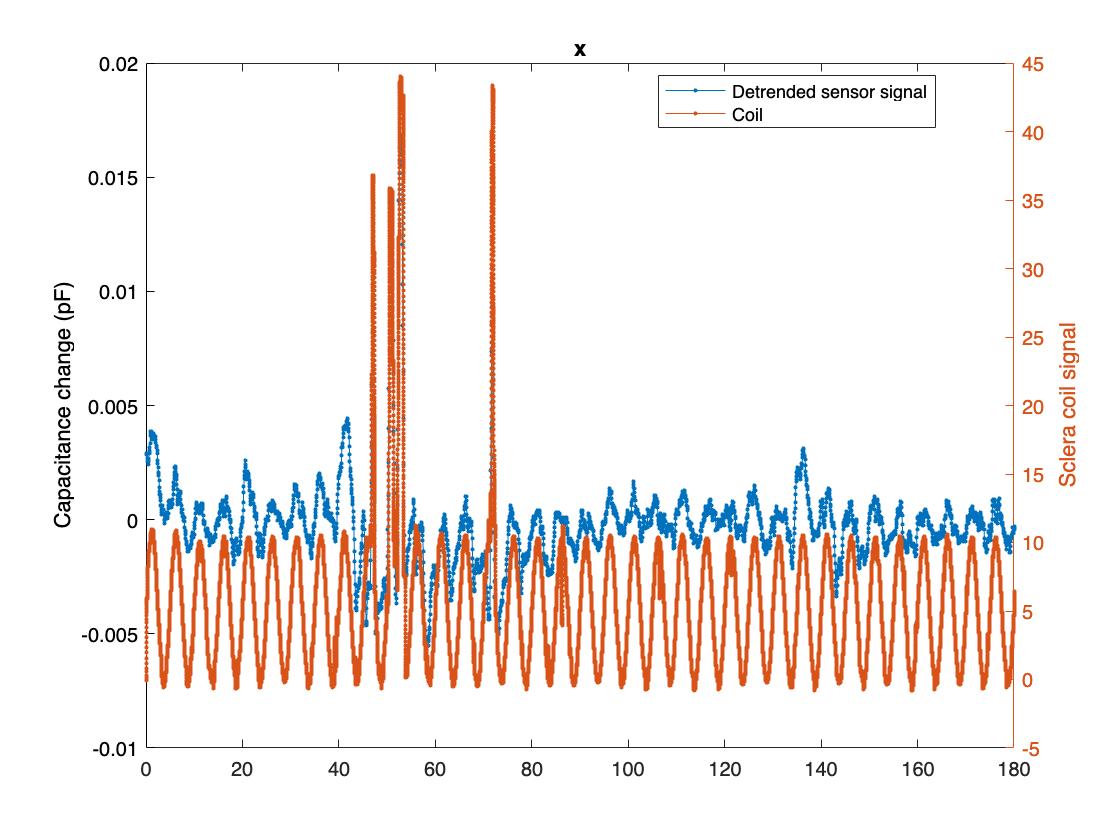

clf
capDataMain = -capDataSmoothPursuit0_2; 

csmall = find(capDataMain==min(capDataMain));
capDataMain(csmall) = [];

% Outlier removal optional
capDataMain = filloutliers(capDataMain,'previous','movmedian',3);

mainCoil = smoothPursuit0_2;

coilTime = linspace(1,length(mainCoil),length(mainCoil))*0.001;
capTime = linspace(1,length(capDataMain),...
    length(capDataMain))/sampling_rate;

%= Data Preprocessing
capDataPreproc = detrend(capDataMain,2);
capDataPreproc = circshift(capDataPreproc,-20);

%=
% Data Processing Handle fx
capDataProcessed = capDataPreproc;
%=

yyaxis left
plot(capTime,movmean(capDataProcessed,10),'.-')
% ylim([-7e-3 7e-3])
ylabel("Capacitance change (pF)")
hold on
yyaxis right
plot(coilTime,mainCoil,'.-')
ylabel("Sclera coil signal")
% ylim([-13 23])
xlim([0 180])
hold off
legend("Detrended sensor signal","Coil",Location="best")
title("x")

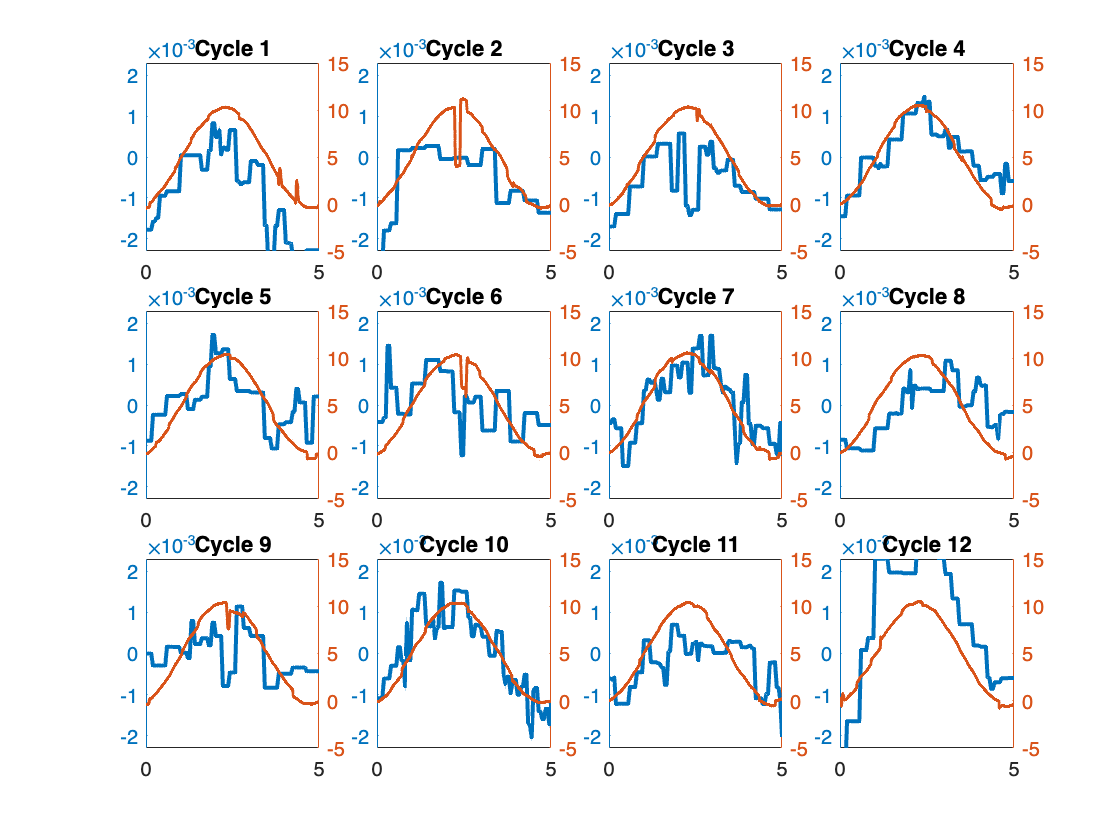

PERIOD_TIME  = 5;
WL_DEN_LVL = 3; 
WL_THR_MTD = 'Bayes'; 
WL_TYPE = 'bior1.5';

START_TIME = 79;

capDataLocal = capDataPreproc;
coilDataLocal = mainCoil;

corra = zeros(1,16);
clear outarr


locs = floor(START_TIME*sampling_rate+1):floor(PERIOD_TIME*sampling_rate):length(capDataLocal);
coilLocs = 1000*START_TIME+1:floor(PERIOD_TIME*1000):length(coilDataLocal);
for peaknum = 1 : min([length(locs)-1 16]) 

    outarr{peaknum,1} = wlcomp(capDataPreproc(locs(peaknum):locs(peaknum+1)),WL_TYPE,WL_DEN_LVL,0);
    outarr{peaknum,2} = capDataPreproc(locs(peaknum):locs(peaknum+1));

end
clear capvar coilvar
coilvar = [];
capvar = [];
clf
tiledlayout(3,4,'TileSpacing','tight')
for ix = 1:12
    nexttile
    if ix <= length(outarr)

        yyaxis left
        tsCap = linspace(0,PERIOD_TIME,length(outarr{ix,1}));
        tsCoil = linspace(0,PERIOD_TIME,PERIOD_TIME*1000 + 1.2);
        plot(tsCap, outarr{ix,1},LineWidth=2);
        hold on

        ylim([-2.3e-3 2.3e-3])
        yyaxis right

        plot(tsCoil,coilDataLocal(coilLocs(ix):coilLocs(ix+1)),LineWidth=1.5);
        hold on

        ylim([-5 15])
        hold off
        xlim([0 5])
        dsCoil = interp1(tsCoil,coilDataLocal(coilLocs(ix):coilLocs(ix+1)),tsCap);
        coilvar = [coilvar;dsCoil'];
        capvar = [capvar;outarr{ix,1}];
        mincorr = min(corrcoef(dsCoil,outarr{ix,1})); 
        corra(1,ix) = mincorr(1);
    end
    title("Cycle " + ix);
end

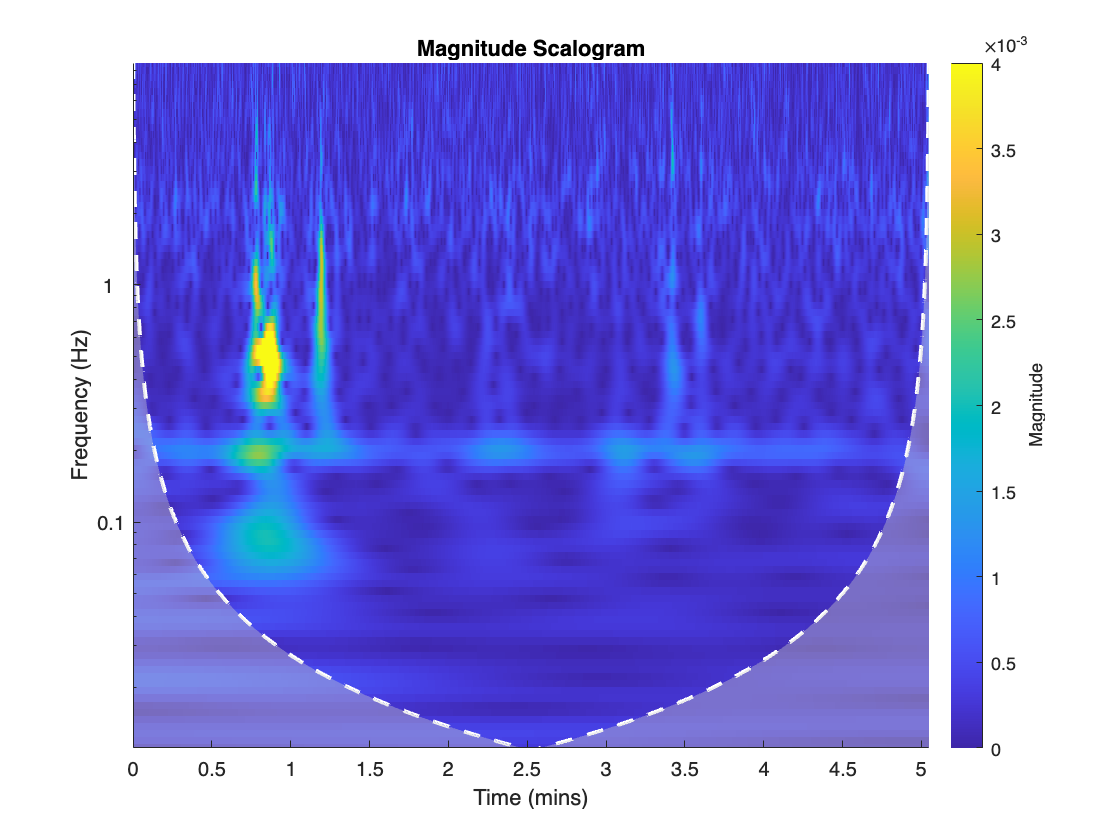

cwt(capDataPreproc,sampling_rate)
caxis([0 4e-3])

max(corra(corra ~= 0))

ans = 0.8994

mean(corra(corra ~= 0))

ans = 0.7074

std(corra(corra ~= 0))

ans = 0.1629

[xData, yData] = prepareCurveData( coilvar, capvar );
ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Robust = 'Bisquare';
[fitresult, gof] = fit( xData, yData, ft, opts );

Denoise Function Implementations

function wl_out = wlcomp(signal_in,wltype,lvl,thr_in)
    [thr,sorh,keepapp] = ddencmp('den','wv',signal_in);
    if thr_in ~= 0
        thr = thr_in;
    end
    wl_out = wdencmp('gbl',signal_in,wltype,lvl,thr,sorh,keepapp);
end
